# Practice 1: Energy Expenditure and Smartphones

This is a [matlab script](https://it.mathworks.com/help/matlab/matlab_prog/create-scripts.html), sought for plotting raw acceleration, `IAA_tot` (**Task 1.1.2**) and `EE` (**Task 1.2.3**) values, based on the data logged to the [MathWorks cloud](https://it.mathworks.com/help/matlabmobile/ug/log-in-to-the-cloud.html) from a smartphone. 

## How should students use this script?

Be this script launched in Matlab desktop or in your [Matlab Online](https://it.mathworks.com/products/matlab-online.html) account, be sure that it is located and run in the same folder where the "**reference**" folder is located: this is where reference functions for processing the acceleration data into `IAA_tot` values (***fromBufferedAccToIaaTot_ref.p***) and then into `EE` values (***fromIaaTotToEE_ref.p***) are located.

- to process acceleration data using the students' rather than the functions in the "**reference**" folder, update the code lines number 109 (for **Task 1.1.1**) and number 110 (**Task 1.2.2**).

***ATTENTION, FOR THIS SCRIPT TO WORK THE FOLLOWING POINTS MUST BE OBSERVED:***

- [MATLAB Mobile](https://it.mathworks.com/products/matlab-mobile.html) application has been already installed and set up in the target, smartphone device.

- Signing to the [MathWorks cloud](https://it.mathworks.com/help/matlabmobile/ug/log-in-to-the-cloud.html) is necessery for establishing communication between a Matlab instance and the smartphone.

- Support Package for either [Android](https://it.mathworks.com/help/supportpkg/mobilesensor/index.html?searchHighlight=support%20package%20for%20android%20sensor&s_tid=srchtitle_support%20package%20for%20android%20sensor_1) or [iOS](https://it.mathworks.com/help/supportpkg/iossensor/index.html?searchHighlight=support%20package%20ios%20sensor&s_tid=srchtitle_support%20package%20ios%20sensor_1) sensors has been already installed.

A very simple example on how to stream smartphone sensor data to Matlab is provided in this [tutorial](https://it.mathworks.com/help/matlabmobile/ug/sensor-data-streaming-tutorial.html).

## What students are expected to do?

This script is intended only for the real-time visualisation, and acquisition, of acceleration data streamed from a smartphone.  As for the simulation version of this script (***inspectingIaaAndEE_simulation.mlx***), four plots are created, three showing accelerations in the three directions ($a_x$, $a_y$ and $a_z$), and one showing current and past `IAA_tot` and `EE` values.  

**When closing the figure, all acceleration data logged up to when the figure was closed is saved to the Matlab workspace.**

NO INPUT IS REQUIRED FOR RUNNING THIS SCRIPT, **OTHER THAN ENSURING THE FUNCTIONS WRITTEN IN TASKS 1.1.1 AND 1.2.2 WORK PROPERLY**, IF NOT USING THE REFERENCE FUNCTIONS.

## The code - matlab script

This supporting script is completed, with the sole aim of providing students with a means of visualising and acquiring acceleration data.

### Clearing and closing

Start by closing any existing figures

close all

### Establishing connection with smartphone

The function [mobiledev](https://it.mathworks.com/help/matlabmobile_android/ref/mobiledev.html?searchHighlight=mobiledev&s_tid=srchtitle_mobiledev_1) is run here in an attempt to establish a connection with the target, smartphone.  If unsuccessful, a message with the error cause is issued to the user.

if not(exist("m","var"))
    clearvars
    try
        % by default, this script relies on the reference functions for
        % computing IAA_tot and EE values (cf lines 110 and 111).  For this reason,
        addpath("reference") % the "reference" folder is added to search path
        m = mobiledev; % Establishing connection with the smartphone
        fprintf("Connection with smartphone established\n")
        disp(m) % provide feedback to user on connection status
    catch ME
        % if connection was not established, issue the cause to the user
        errordlg(sprintf("Failure reason:\n\n%s\n",ME.message),"Communication with smartphone failed")
    end
end

### Creating a timer object

If acceleration data streamed from the smartphone are to be processed and shown in real time to user, we must retrieve the streamed data at a regular rate.  This can be done using a Matlab [timer object](https://it.mathworks.com/help/matlab/ref/timer.html?searchHighlight=timer&s_tid=srchtitle_timer_1).  As set below, the timer object attempts to fire an event at a fixed rate, every second.  The actual time between events is shown to the user, indicating how regularly the streamed data is logged into the Matlab workspace.

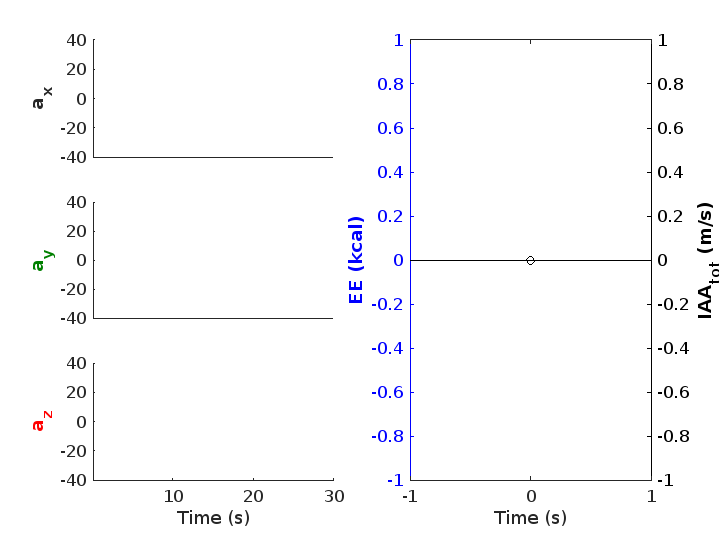

if exist("m","var") % if connection has been established with the smartphone
    
    if not(exist("t","var")) || not(isobject(t)) % if timer object does not exist 
        t = timer("ExecutionMode","FixedRate","Period",1,"BusyMode","drop","ErrorFcn","stop(t),fprintf('Error found. Stopping timer\n')"); % create it
    end

    % if figure handle does not exist or the figure has been deleted
    if not(exist("fig","var")) || not(isgraphics(fig))
        % creating graphic objects
        fig = figure("Visible","on","Units","normalized","Position",[.3 .25 .5 .6],"ToolBar","figure"); % create the figure for plotting data
        [p.l, p.ax] = createGraphicObjs(m.SampleRate,fig,30); % create axes and lines for the current figure
        % then set the callback for handling changes in Y limits and for the closure of the figure
        set(fig,"KeyPressFcn",{@setYaxesLimits,p.ax(1:3)},"CloseRequestFcn",{@closeFigure,t,m})
    end

    % formally declare the need to initialize parameters necessary for reading logged data
    filter_acceleration = true; % whether to filter raw acceleration data or not
    body_mass = 60; % (kg) individual body mass
    p.initialize_parameters = true; % These parameters are declared in the TimerFcn
    clear fromIaaTotToEnergyExpenditure_ref % why is this clear necessary?
    setappdata(0,"parameters",p) % storing the p structure, to be used by the TimerFcn
    t.TimerFcn = {@timerFcn,m,30,filter_acceleration,body_mass};
    start(t) % start the timer (from this moment the callback will be triggered every 1 s)
end

After starting the timer, every 1 s the **TimerFcn** function (`timerFcnCallback` function coded below), will be run. The 1 s period should be sufficient long to avoid queueing conflicts: that is, firing an event when the previous call to the callback function is still running.  Otherwise, the "Period" property above should be increased.  A detailed description on how Matlab handle conflicts is provided [here](https://it.mathworks.com/help/matlab/matlab_prog/handling-timer-queuing-conflicts.html).

## Nested functions

This section contains Matlab functions meant for handling calls to the [TimerFcn](https://it.mathworks.com/help/matlab/matlab_prog/timer-callback-functions.html), triggered by the timer object at a regular interval, for creating the graphic objects (axes and lines), and for managing when to stop communication with the smartphone (just close the figure) and to change the limits of the Y axis. Four functions are coded below:

### Timer object callback (TimerFcn)

This function runs every second.  To increase or decrease the interval between consecutive calls to this callback the user may set the "`Period`" property when creating the timer object above.  Be careful though that decreasing the timer period may result in a progressive delay in retrieving, processing and plotting real-time data: the interval between function calls must be longer than the time taken to process and plot data.

function timerFcn(src,~,m,T,filter_acceleration,body_mass)
%
% INPUT ARGUMENTS:
%   src - handle for the timer object
%   ~ - indicates the second input argument (i.e., event) of the TimerFcn is not used here
%   m - mobile device object.
%   fig - handle to figure housing axes
%   ax - handles to axes where data will be plotted

    p = getappdata(0,"parameters");
    
    % initializing some variables in the first call to the function 
    if p.initialize_parameters
        %% initialization of general parameters
        p.last_sample_to_read = 0;
        p.last_sample_written_to_buffer = p.last_sample_to_read; % number of samples written to the buffer or exceeding the number of samples corresponding to T s
        m.SampleRate = 50; % ensure acceleration is sampled at 50 Hz
        p.acc_buffer = nan(m.SampleRate*T,3); % acceleration buffer with nRows equal to the number of samples leading to T s
        p.initialize_parameters = false;
    
        %% checking connection status and logging
        if not(m.Connected) % if the device is not connected
            errordlg("Ensure Matlab Mobile is running in your device and is connected to internet.  Timer will be stopped now","Device not connected")
            stop(src)
        else
            fprintf("Discarding any existing logged data\n")
            discardlogs(m) % ensure logging starts now by discarding existing logs
            if not(m.Logging) % if device is connected but not logging data
                fprintf("The devce is not logging data to the Mathworks cloud. Will now attempt to start logging data\n")
                if  not(m.AccelerationSensorEnabled)
                    m.AccelerationSensorEnabled = 1;
                end
                m.Logging = 1; % start logging data to the cloud
            end
        end
        setappdata(0,"parameters",p)
        return
    end
    
    %% retrieving logged, acceleration values
    p.first_sample_to_read = p.last_sample_to_read; % updating the first sample to read from the logged data
    a_xyz = accellog(m); % retrieving data logged to the cloud
    if isempty(a_xyz)
        return % do nothing if no data has been logged yet
    end
    p.last_sample_to_read = size(a_xyz,1); % updating last sample to read from the logged data
    
    % if device goes to background it may not update the Connected and Logging properties readily 
    % we therefore must control for that by asking whether first and last samples to read coincide.
    % If this is the case then no new data has been logged
    if p.last_sample_to_read == p.first_sample_to_read % if so, issue an error message to the user
        errordlg("Connection with the device has been lost. Timer will be stopped","Connection lost")
        stop(src) % stop timer
        return % and return
    end
    
    %% warn user about the number of logged values (samples and s units) and the averate time between executions of the callback
    fprintf("Logged values: %d (%3.1f s), time between last two, Timer executions: %3.2f s\n",[[1 1/m.SampleRate]*p.last_sample_to_read src.InstantPeriod])
    
    %% writting samples to buffer
    n_samples_to_be_written = p.last_sample_to_read - p.first_sample_to_read; % number of samples to be written
    %last_retrieved_a_xyz = a_xyz( (1:n_samples_to_be_written) + p.first_sample_to_read,:); % taking the most recent, logged data
    p.acc_buffer( (1:n_samples_to_be_written)+p.last_sample_written_to_buffer , :) = ...
        a_xyz( (1:n_samples_to_be_written) + p.first_sample_to_read,:); % buffering most recent acceleration values
    p.last_sample_written_to_buffer = p.last_sample_written_to_buffer + n_samples_to_be_written; % update pointer location in the buffer
    
    set(p.l(1:3),{"YData"},num2cell(p.acc_buffer(1:T*m.SampleRate,:),1)'); % do not remove curly braces: they are necessary

#### Processing acceleration data

This is where `IAA_tot` (**Task 1.1.1**) and `EE` (if in **Task 1.2.2**) values are computed, by calling the reference (or the students') functions. 

    %% process acceleration data
    if p.last_sample_written_to_buffer > T*m.SampleRate % if 30 s have elapsed
        IAA_tot = fromBufferedAccToIaaTot_ref(p.acc_buffer(1:T*m.SampleRate,:), filter_acceleration, m.SampleRate); % Task 1.1.1 (processing raw acceleration)
        EE = fromIaaTotToEnergyExpenditure_ref(IAA_tot,body_mass);

Resuming the callback

        yyaxis right % updating IAA_tot values
        set(p.l(4),"XData",[p.l(4).XData p.l(4).XData(end)+T] ,"YData",[p.l(4).YData IAA_tot])
        
        % remove comments for both lines below if in Task 1.2.3
        yyaxis left % updating EE values
        set(p.l(end),"XData",[p.l(end).XData p.l(end).XData(end)+T],"YData",[p.l(end).YData EE])
    
        p.last_sample_written_to_buffer = p.last_sample_written_to_buffer - T*m.SampleRate; % amount of samples to retain (not processed)
        p.acc_buffer(1:T*m.SampleRate,:) = nan; % setting to nan the processed, acceleration samples
        p.acc_buffer = circshift(p.acc_buffer,-T*m.SampleRate,1); % shifting remaining samples to process to the beggining of the buffer
    end

    % updating the p structure stored in app data
    setappdata(0,"parameters",p)
end

### Creating graphic objects

This function creates the figure where raw acceleration data, `IAA_tot` values, and `EE` estimates will be plotted.  The later one will be shown only in **Task 1.2.3**.

function [l, ax] = createGraphicObjs(sf,fig,T)
%
% INPUT ARGUMENTS:
%   sf - Sampling rate (Hz) used for logging acceleration data
%   fig - handle to the figure created for plotting
%   T - period, in seconds, over which accelration values are integrated.
%
% OUTPUT ARGUMENTS:
%   l - handle to line objects (raw acceleration, IAA_tot, and EE values)
%   ax - handle to axes where values are shown

    % creating graphs for raw, acceleration data
    ax(1) = subplot(3,2,1,"Parent",fig); % graph for x acceleration (a_x)
    l(1) = line(ax(1),(1:T*sf)/sf,nan(T*sf,1)); % line for a_x
    
    ax(2) = subplot(3,2,3,"Parent",fig); % graph for y acceleration (a_y)
    l(2) = line(ax(2),(1:T*sf)/sf,nan(T*sf,1),"Color",[0 .5 0]); % line for a_y
    
    ax(3) = subplot(3,2,5,"Parent",fig); % graph for z acceleration (a_z)
    l(3) = line(ax(3),(1:T*sf)/sf,nan(T*sf,1),"Color","r"); % line for a_z
    
    % setting properties for the three axes just created
    set(ax(1:2),"XTick",[]) % removing time ticks for the first two axes
    set(ax(1:3),"XLim",[1/sf T],"YLim",[-1 1]*40,"FontSize",12,"FontName","Arial") % setting limits
    ylabel(ax(1),"a_x","FontWeight","bold") % labelling a_x 
    ylabel(ax(2),"a_y","Color",[0 .5 0],"FontWeight","bold") % labelling a_y 
    ylabel(ax(3),"a_z","Color","r","FontWeight","bold") % labelling a_z 
    xlabel(ax(3),"Time (s)"); % xlabel, used for providing feedback on elapsed time
    
    % creating graph for the IAA_tot and EE values
    colororder({'b','k'}) % specifying color for left and right y axes
    ax(4) = subplot(3,2,(2:2:6),"Parent",fig); % IAA graph
    
    yyaxis right % IAA scale at the right side
    l(4) = stem(0,0,"Color","k","LineWidth",1); % initializing IAA_tot line object
    ylabel("IAA_{tot} (m/s)","FontWeight","bold") % y left label (IAA_tot)
    yyaxis left %% EE scale at the left side
    l(end+1) = stairs(0,0,"Color","c","LineWidth",8); % initializing EE line object
    xlabel("Time (s)") % xlabel (time)
    ylabel("EE (kcal)","FontWeight","bold") % y right label (EE)
    set(ax(4),"FontSize",12,"FontName","Arial") % setting font properties for IAA graph
end

### Stopping data streaming

This function is triggered by when the user attempts to close the figure.  The intention to close the figure is used here to interrupt data streaming and to set the conditions for restarting data streaming.

function closeFigure(src,~,t,m)
%
% INPUT ARGUMENTS:
%   src - handle to the figure that is to be closed
%   t - object created with the timer function
%   m - object created with the mobiledev function
%
%
% when the user clicks on the figure close button:

set(src,"KeyPressFcn",[],"CloseRequestFcn",[]) % disabling figure callbacks (necessary for saving it as a .fig file)
time_now = datetime('now','TimeZone','local','Format','d-MMM-y_HH-mm-ss'); % current, formatted time
savefig("Figure_" + string(time_now)); % saving the figure in .fig format
delete(src), % close the current figure

stop(t), % the timer object is stopped
m.Logging = 0; % logging of acceleration data is set to false
m.AccelerationSensorEnabled = 0; % disabling accelerometer
pause(1), % ensure logging of data was stopped before:
[a_xyz, t_stamps] = accellog(m); % retrieving all logged data
save("logged_axyz_" + string(time_now),"a_xyz","t_stamps") % save acceleration in .mat format

discardlogs(m), % discarding all logs
fprintf('Ended session\n') % inform user the acquisition session has ended successfully

end

### Setting Y Lims

The next lines handle the callback triggered by when the user presses a key while the Matlab figure is active.  By pressing **uparrow **or **downarrow **in the keyboard the limits of the Y axis for the raw acceleration data respectively **increase **or **decrease **by **10 **${\textrm{ms}}^{-2}$.

function setYaxesLimits(~,event,ax)
    switch event.Key % the key pressed
        case "uparrow" % if uparrow
            set(ax,"YLim",[-1 1]*max(ax(1).YLim(2)+[0 5])) % increment Y Lim by 5, indeliberately
        case "downarrow"
            set(ax,"YLim",[-1 1]*max([ax(1).YLim(2)-5 5])) % decrement Y Lim by 5
    end
end